load('positionmatrix.mat')
pm=positionmatrix;pm=cell2mat(pm);
walls=double(walls);
acclTime=0.5;
bodyFactor=120000;
F=2000;
delta=0.08*50;

[a,b]=test_walldistance([0.4 0.6],[0 0 1 0])

a = 0.6000

b =      0     1


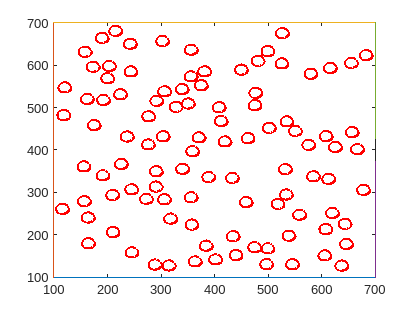

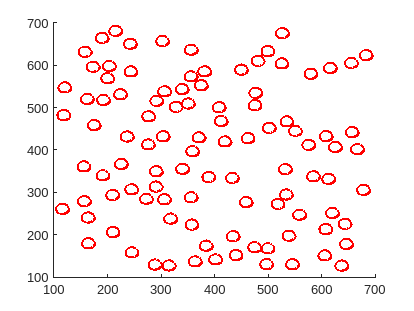

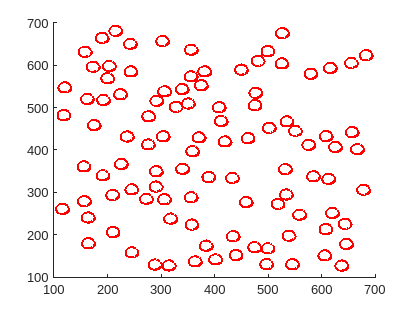

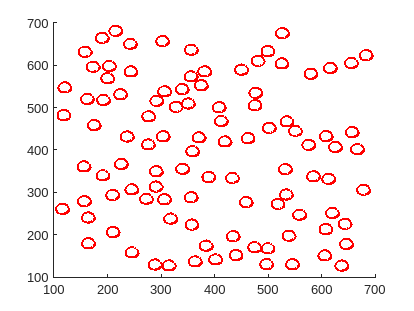

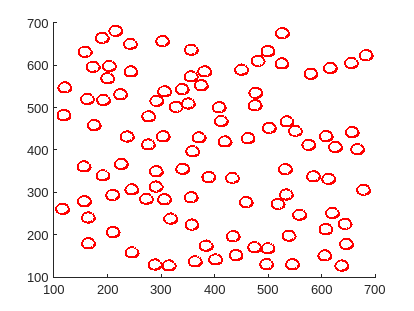

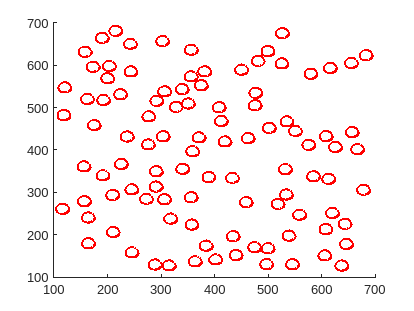

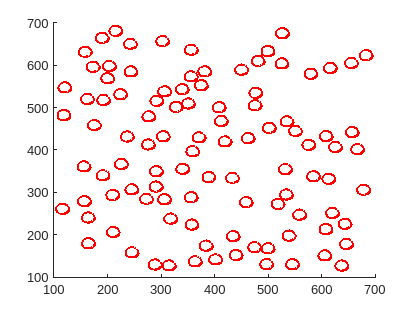

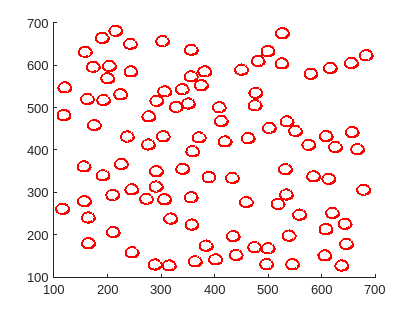

function [dist,npw]=test_walldistance(point, wall)
    p0=wall(1,[1,2]);
    p1=wall(1,[3,4]);
    d=p1-p0;

    ymp0=point-p0;
    t=zdot(d,ymp0)./sqrt(zdot(d,d));

    if t <= 0.0
        dist = zmod(ymp0);
        cross = p0 + t.*d;

    elseif t >= 1.0
        ymp1 = point-p1;
        dist = zmod(ymp1);
        cross = p0 + t.*d;

    else

        cross = p0 + t.*d;
        a=cross-point;
        dist = zmod(a);
    end
    a=cross-point;
    npw = -a./zmod(a);

end

function zdot=zdot(a,b)
    zdot=a(:,1).*b(:,1)+a(:,2).*b(:,2);
end

function znorm=znorm(a)
    znorm=a./zmod(a);
end

function zmod=zmod(a)
    zmod=sqrt(zdot(a,a));
end

% load('finalmat.mat')
% load('positionmatrix.mat')
% 
% x_wall=[walls(:,1) walls(:,3)];
% y_wall=[walls(:,2) walls(:,4)];
% 
% plot(x_wall',y_wall')
% for j=1:10
% timemat=finalmat((1+100*j:100+100*j),:);
% % for i=1:nr_agents
%     hold on
% %     plot(timemat(:,1), timemat(:,2),'.')
%     viscircles([timemat(:,1), timemat(:,2)], timemat(:,4));
%     quiver(timemat(:,1),timemat(:,2),timemat(:,))
%     hold off
%     figure
% % end
% end